### 初始化

clc;
clear

### 参数设置

M = 96000;         % Sample Points
Fs = 10E6;          % Sample Rate
pathname = 'C:\Users\zhaoz\OneDrive\文档\InstrumentStudio Projects\WaveformData (38) Oscilloscope - Waveform Data.csv';


### 数据读取

range_index_head = ['A' num2str(11)];
range_index_tail = ['B' num2str(10+M)];
range_index = [range_index_head ':' range_index_tail];
wave_data = readmatrix(pathname,"Range",range_index);
vout = wave_data(:,1) - wave_data(:,2);

### 计算THD

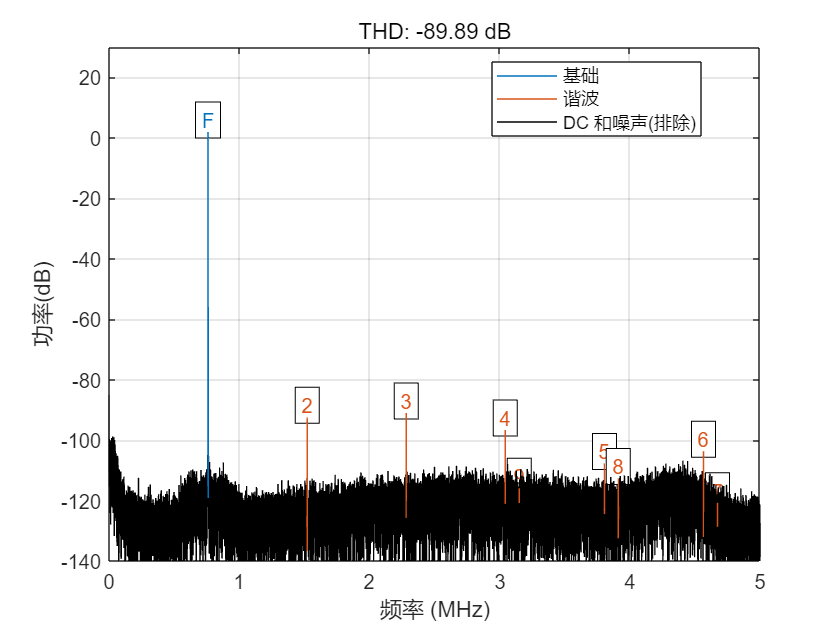

ans = -89.8940

figure
thd(vout, Fs, 9, 'aliased')

### Export results

[r, harmpow, harmfreq] = thd(vout, Fs, 7, 'aliased');
channel = 11

channel = 11

Time = datetime('now', 'InputFormat','dd-MMM-uuuu HH:mm:ss');
THD = r;
HD = harmpow(1:4);          % record THD and base, HD1, HD2, HD3;
fid = fopen('results.csv', 'a+')

fid = 3

fprintf(fid, "%s, %s, %d, %d, %d, %.2f, %.2f, %.2f, %.2f, %.2f\n", ...
    Time, pathname, channel,Fs/1E6,M,THD, HD);
fclose(fid);